initSim

Cbase1v = 0.0150

l_f = 0.0265

r_f = 0.0063

SCR_grid = 5

z_grid = 0.2000

r_grid = 0.0632

x_grid = 0.1897

l_grid = 6.0395e-04

R_grid = 0.0134

L_grid = 1.2780e-04

R_mv = 0.6000

L_mv = 0.0034

x_mv_tot = 113.2518

x_hv_tot = 18.8496

r_mv_tot = 0.0912

r_hv_tot = 0.0013

ans = 1.4293e+03

k_p_p_vsm = 0.6000

k_p_q_vsm = -0.0500

k_d_vsm = 70

H_vsm = 3

ki_q = 314.1593

V_dc_base = 1.1268e+03

V_dc = 1.1268e+03

C_dc = 0.0236

ans = 1.5708

I_dc_base = 1.3312e+03

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


L_f = l_f*Lbase1v

L_f = 1.7849e-05

R_f = r_f*Zbase1v

R_f = 0.0013

C_f = 0.0757204*Cbase1v

C_f = 0.0011

% plant
    
G_plant = 1/(s*L_f+R_f)

G_plant =
 
            1
  ----------------------
  1.785e-05 s + 0.001333
 
Continuous-time transfer function.
Model Properties




f_sw = 10000

f_sw = 10000

omega_c = f_sw/5*2*pi

omega_c = 1.2566e+04

f_c = omega_c/(2*pi)

f_c = 2.0000e+03

Tau_cc = 1/f_c

Tau_cc = 5.0000e-04


Kp_cc = L_f/Tau_cc%1/Vbase_lv;

Kp_cc = 0.0357

Ki_cc = R_f/Tau_cc %1/f_c%Kp_cc*omega*(100.*omega*l_f + 71.*r_f)/(71.*omega*l_f - 100.*r_f); 

Ki_cc = 2.6662

% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)
G_cc = Kp_cc + Ki_cc/s

G_cc =
 
  0.0357 s + 2.666
  ----------------
         s
 
Continuous-time transfer function.
Model Properties



v_od = 1;
v_od_m = v_od

v_od_m = 1



i_fd = 0;
i_fd_m = i_fd;
i_fd_ref = 1;
i_fq = 0;
i_fq_m = i_fq;

e_fd = i_fd_ref-i_fd_m;

omega = omega_nom/omega_nom

omega = 1



v_td = e_fd*G_cc-omega*L_f*i_fq_m-v_od_m;

i_fd = (v_td - v_od)*G_plant;

G_openl = G_cc*G_plant

G_openl =
 
       0.0357 s + 2.666
  --------------------------
  1.785e-05 s^2 + 0.001333 s
 
Continuous-time transfer function.
Model Properties


G_cl = G_openl/(1+G_openl)

G_cl =
 
          6.372e-07 s^3 + 9.518e-05 s^2 + 0.003554 s
  ----------------------------------------------------------
  3.186e-10 s^4 + 6.848e-07 s^3 + 9.695e-05 s^2 + 0.003554 s
 
Continuous-time transfer function.
Model Properties


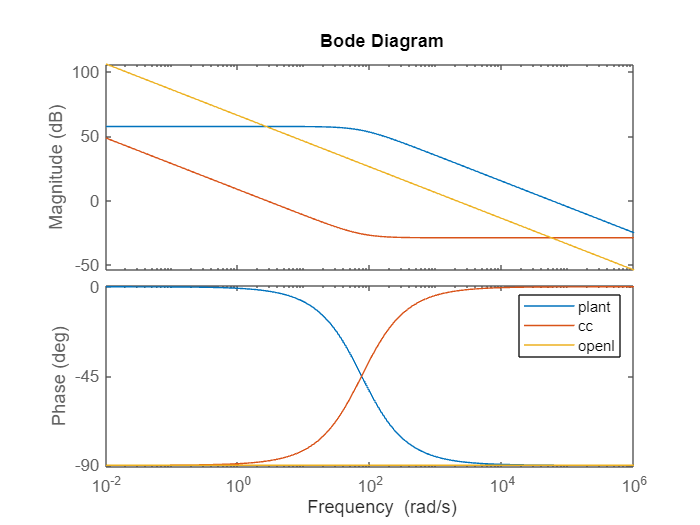


bode(G_plant,G_cc,G_openl,{10e-3,10e5})
legend('plant', 'cc','openl')

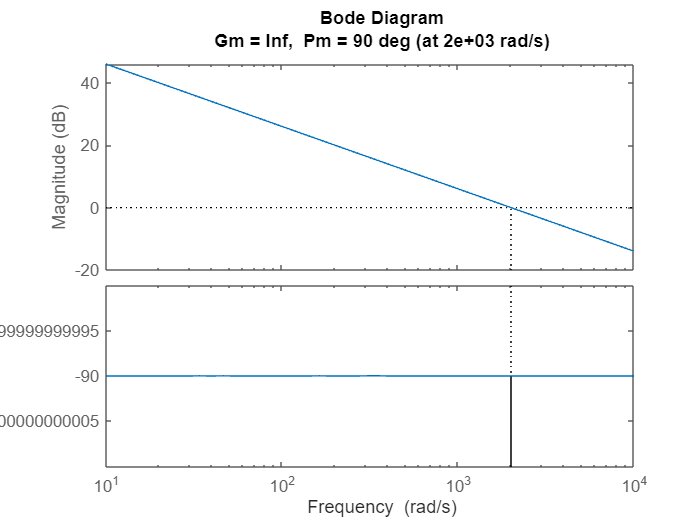



margin(G_openl)

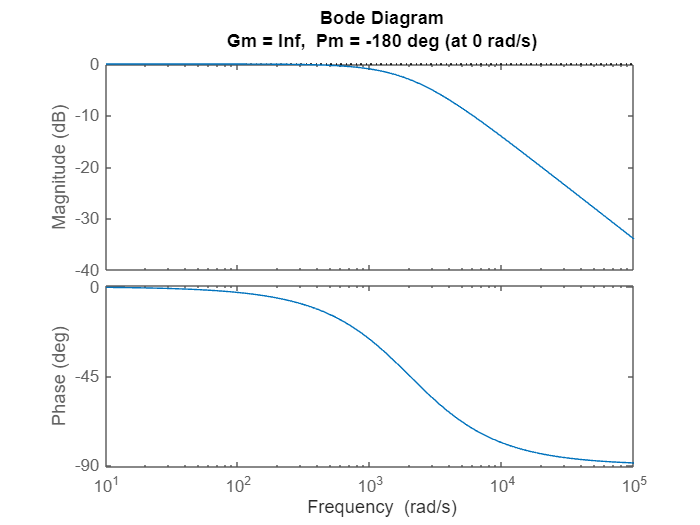

margin(G_cl)

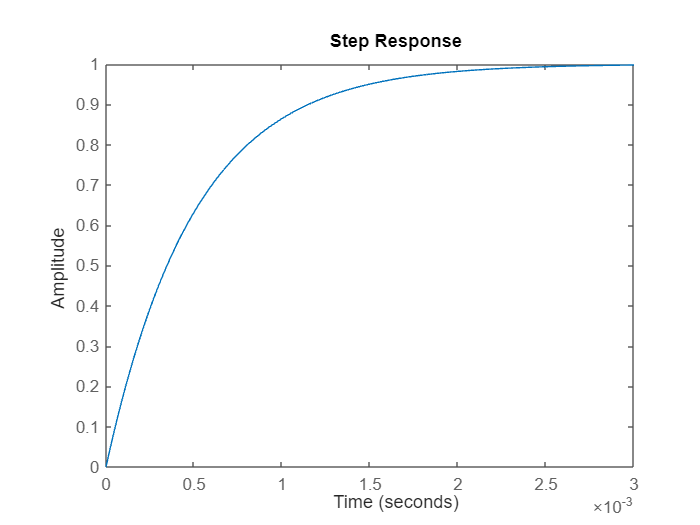

step(G_cl)

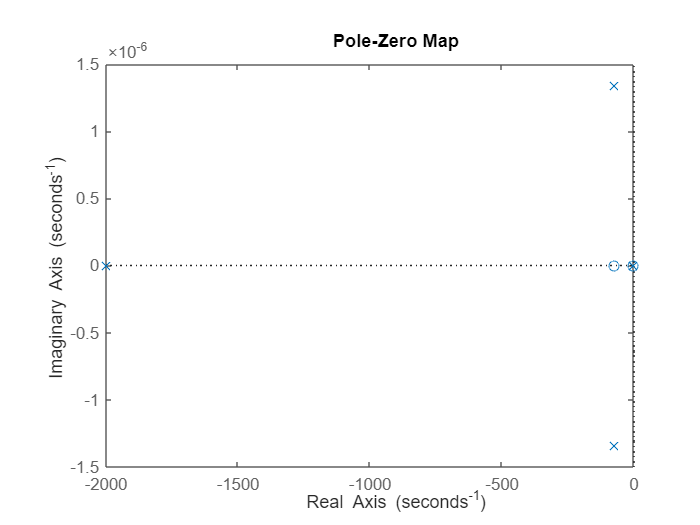

pzmap(G_cl)

Kp_vc = 47%0.05 %0.05%1/Vbase_lv;

Kp_vc = 47

Ki_vc = 200 %1/f_c%Kp_cc*omega*(100.*omega*l_f + 71.*r_f)/(71.*omega*l_f - 100.*r_f); 

Ki_vc = 200


% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)
G_vc = Kp_vc + Ki_vc/s

G_vc =
 
  1.5e06 s + 200
  --------------
        s
 
Continuous-time transfer function.
Model Properties



G_openl = G_vc*G_cc*G_plant

G_openl =
 
  5.355e04 s^2 + 3.999e06 s + 533.2
  ---------------------------------
    1.785e-05 s^3 + 0.001333 s^2
 
Continuous-time transfer function.
Model Properties


G_cl = G_openl/(1+G_openl)

G_cl =
 
          0.9558 s^5 + 142.8 s^4 + 5331 s^3 + 0.7108 s^2
  --------------------------------------------------------------
  3.186e-10 s^6 + 0.9558 s^5 + 142.8 s^4 + 5331 s^3 + 0.7108 s^2
 
Continuous-time transfer function.
Model Properties


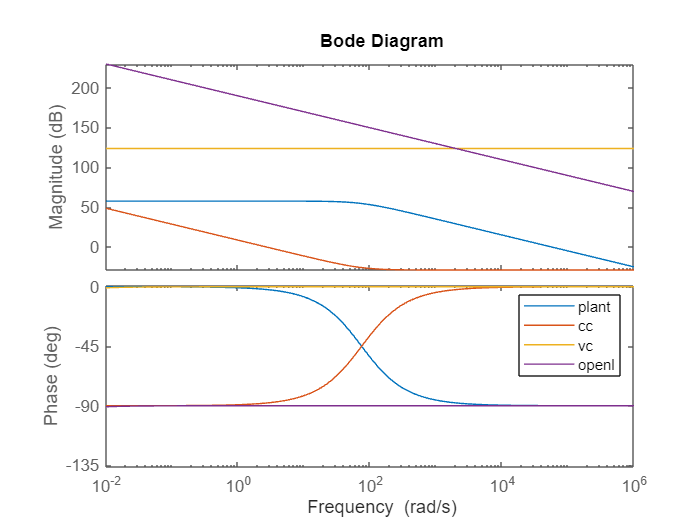


bode(G_plant,G_cc,G_vc,G_openl,{10e-3,10e5})
legend('plant', 'cc','vc','openl')

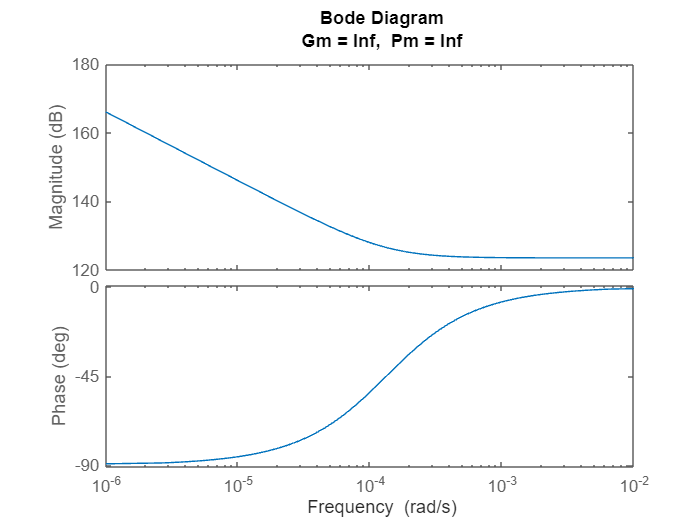


margin(G_vc)

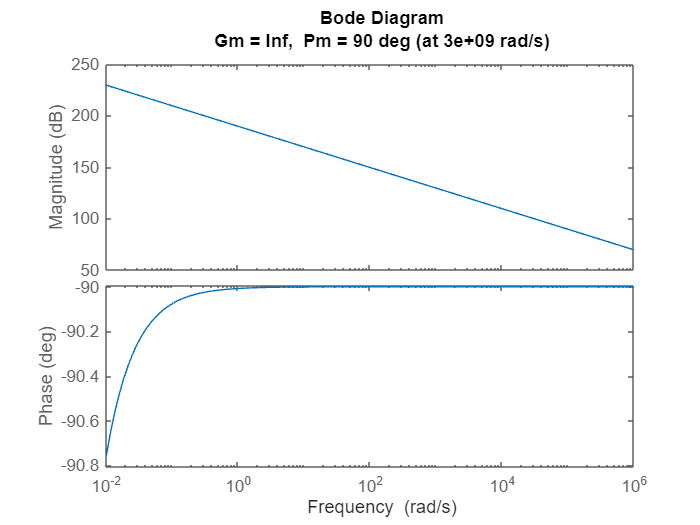

margin(G_openl,{10e-3,10e5})

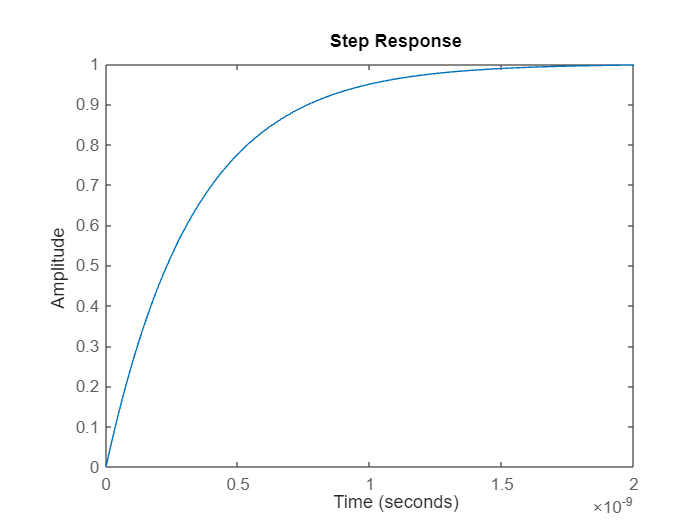


step(G_cl)

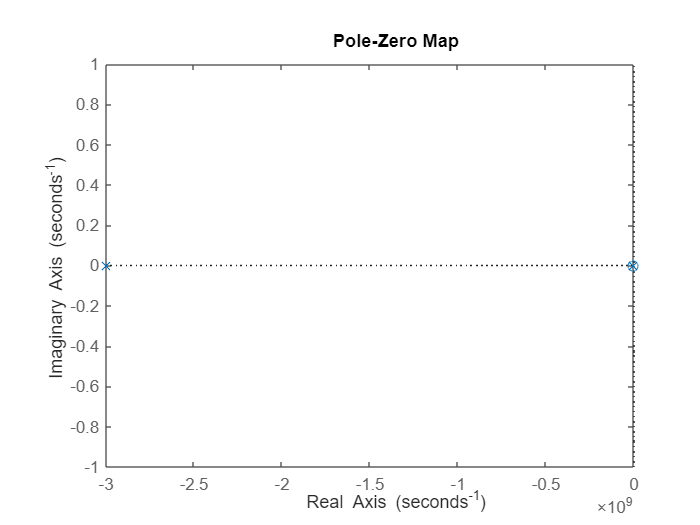

pzmap(G_cl)



asind((1-200*Tau_cc)/(1+200*Tau_cc))

ans = 54.9032

sqrt(Ki_vc*1/Tau_cc)

ans = 632.4555

ans*0.0757204

ans = 47.8898

% droop control

% (wmeas-wref)/(Pref-Pmeas) = kp_p

kp_p = (0.95-1)/(0.5-1)%0.05

kp_p = 0.1000


% (vmeas-vref)/(Qref-Qmeas) = -kp_q
kp_q = (0.9-1)/(0-0.5)

kp_q = 0.2000